a = sData.a_mPs2; 
v = sData.v_mPs; 
t = sData.t; 
Fr = sData.F_friction; 
x = sData.xc_m; 

v_b'nin bulunması 

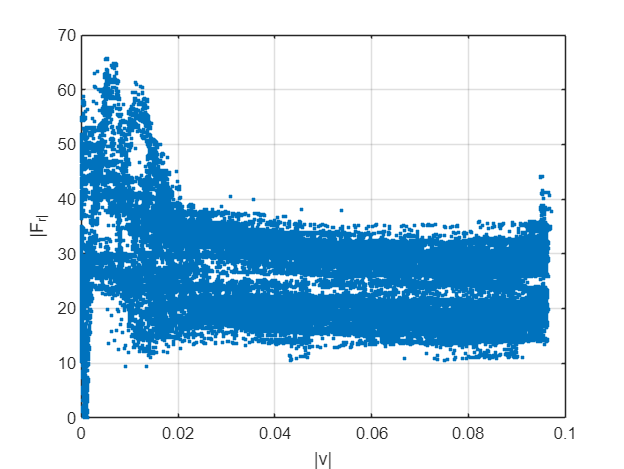

figure
plot(abs(v), abs(Fr), '.')
xlabel('|v|')
ylabel('|F_r|')
grid on

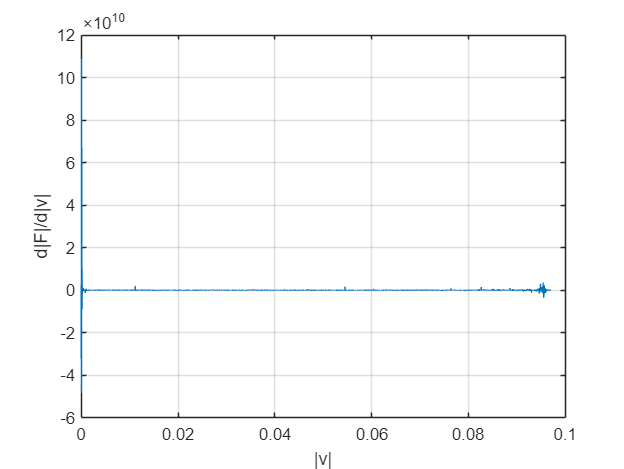


[v_sorted, idx] = sort(abs(v));
F_sorted = abs(Fr(idx));

dFdv = gradient(F_sorted, v_sorted);

figure
plot(v_sorted, dFdv)
xlabel('|v|')
ylabel('d|F|/d|v|')
grid on

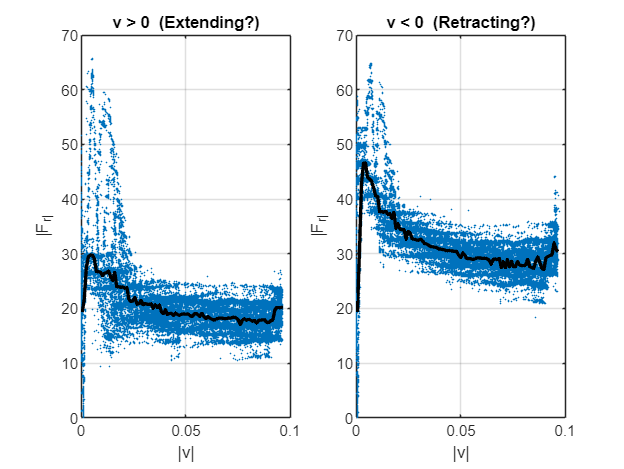

a  = sData.a_mPs2;
v  = sData.v_mPs;
t  = sData.t;
Fr = sData.F_friction;
x  = sData.xc_m;

% --- Yön maskeleri ---
mPos = v > 0;
mNeg = v < 0;

% --- Pozitif yön: |F|-|v| ---
vPos = abs(v(mPos));
FPos = abs(Fr(mPos));

% --- Negatif yön: |F|-|v| ---
vNeg = abs(v(mNeg));
FNeg = abs(Fr(mNeg));

% --- Figür: iki subplot ---
figure; clf;

subplot(1,2,1);
plot(vPos, FPos, '.', 'MarkerSize', 3); hold on; grid on;
title('v > 0  (Extending?)');
xlabel('|v|'); ylabel('|F_r|');

subplot(1,2,2);
plot(vNeg, FNeg, '.', 'MarkerSize', 3); hold on; grid on;
title('v < 0  (Retracting?)');
xlabel('|v|'); ylabel('|F_r|');

% --- (Opsiyonel ama faydalı) Bin'lenmiş medyan eğrisi: dirseği netleştirir ---
nbin = 100;                     % istersen 40-100 arası oynat
vMax = max(abs(v));

edges = linspace(0, vMax, nbin+1);
cent  = 0.5*(edges(1:end-1) + edges(2:end));

medPos = nan(size(cent));
medNeg = nan(size(cent));

for i = 1:nbin
    iPos = vPos >= edges(i) & vPos < edges(i+1);
    iNeg = vNeg >= edges(i) & vNeg < edges(i+1);

    if any(iPos), medPos(i) = median(FPos(iPos)); end
    if any(iNeg), medNeg(i) = median(FNeg(iNeg)); end
end

subplot(1,2,1);
plot(cent, medPos, 'k-', 'LineWidth', 2);

subplot(1,2,2);
plot(cent, medNeg, 'k-', 'LineWidth', 2);

a  = sData.a_mPs2;
v  = sData.v_mPs;
Fr = sData.F_friction;

v_b_pos = 0.025;
v_b_neg = 0.040;

stat = fit_static_params_tran(a, v, Fr, v_b_pos, v_b_neg);

stat.pos

ans = struct with fields:
           Fs: 18.8984
           Fc: 37.3202
           vs: 0.0139
            n: 2
           vb: 0.0250
        xdata: [8.0286e-04 0.0104 0.0120 0.0136 0.0153 0.0361 0.0377 0.0393 0.0409 0.0426 0.0442 0.0458 0.0474 0.0731 0.0763 0.0779 0.0795 0.0811 0.0827 0.0843 0.0859 0.0875 0.0891 0.0907 0.0923 0.0939 0.0955]
        ydata: [19.2973 22.5704 34.5924 28.7537 31.2112 17.2774 17.3542 17.3033 17.1339 17.2195 17.2033 17.1871 17.1509 18.3237 17.8304 18.1001 18.4308 17.9703 17.9699 18.0517 18.0443 18.2278 18.0637 18.4013 20.4251 20.4068 20.3167]
     yfit_all: [18.9596 26.8175 28.6018 30.2729 31.7732 37.2982 37.3083 37.3139 37.3169 37.3186 37.3194 37.3198 37.3200 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202 37.3202]
         xfit: [8.0286e-04 0.0104 0.0120 0.0136 0.0153]
         yfit: [19.2973 22.5704 34.5924 28.7537 31.2112]
    yfit_used: [18.9596 26.8175 28.6018 30.2729 31.7732]


stat.neg

ans = struct with fields:
           Fs: 17.3452
           Fc: 44.3782
           vs: 0.0029
            n: 2
           vb: 0.0400
        xdata: [8.0894e-04 0.0121 0.0138 0.0170 0.0768 0.0785 0.0801 0.0817 0.0833 0.0849 0.0866 0.0882 0.0898 0.0914 0.0930 0.0946 0.0963]
        ydata: [19.3103 51.3400 42.1112 39.6833 29.2406 29.2110 29.4673 29.7177 29.7210 29.7005 29.7213 29.4397 29.4641 29.4611 29.3087 29.6231 29.6584]
     yfit_all: [19.3111 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782 44.3782]
         xfit: [8.0894e-04 0.0121 0.0138 0.0170]
         yfit: [19.3103 51.3400 42.1112 39.6833]
    yfit_used: [19.3111 44.3782 44.3782 44.3782]


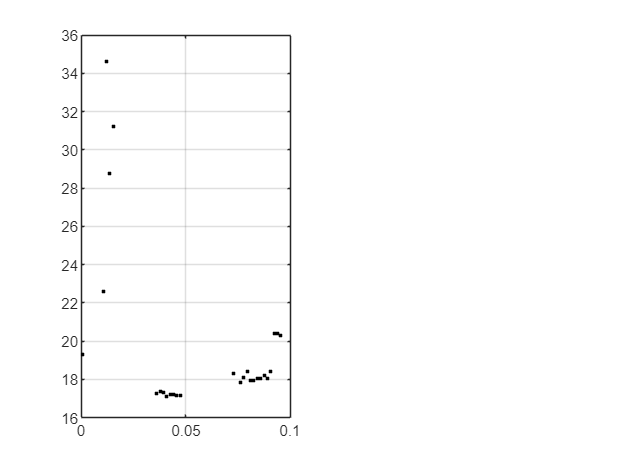


figure; 
subplot(1,2,1); plot(stat.pos.xdata, stat.pos.ydata, 'k.'); hold on; grid on;

plot(stat.pos.xdata, stat.pos.yfit, 'r-', 'LineWidth', 2);

Error using plot
Vectors must be the same length.

title('v>0 static fit'); xlabel('|v|'); ylabel('|F|');

subplot(1,2,2); plot(stat.neg.xdata, stat.neg.ydata, 'k.'); hold on; grid on;
plot(stat.neg.xdata, stat.neg.yfit, 'r-', 'LineWidth', 2);
title('v<0 static fit'); xlabel('|v|'); ylabel('|F|');
